# Exercise 1 


close all
img = im2double(imread('cameraman.tif'));

## Question 2.1.1 / Question 2.1.2

Check out the implementation of pixelValue(image, x, y, interpolationMethod, borderMethod)

## Question 2.1.3

Comparement of (bi)linear and nearest profile.

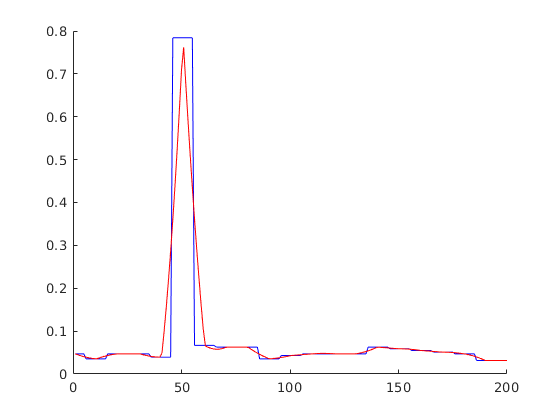

    figure('name', 'Interpolation Profiles (nearest:b vs. linear:r)')
    hold on;
    plot(myProfile(img, 100, 100, 120, 120, 200, 'nearest', 'constant'), 'b');
    plot(myProfile(img, 100, 100, 120, 120, 200, 'linear', 'constant'), 'r');
    hold off;

## Question 2.1.4

pixelValue supports three different border methods: constant, nearest and periodic. See report for discussion on the different methods.

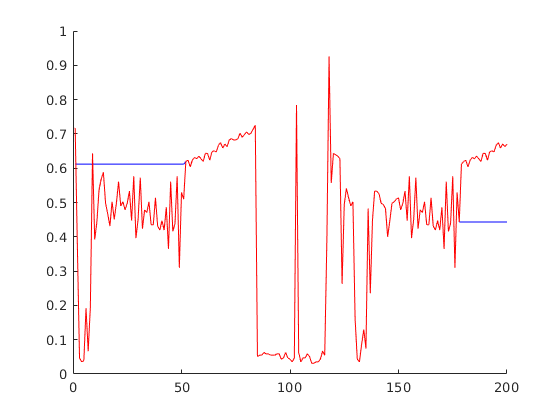

    figure('name', 'Border Methods (nearest:b vs. periodic:r)')
    hold on;
    plot(profile(img, -100, -100, 300, 300, 200, 'nearest', 'nearest'), 'b');
    plot(profile(img, -100, -100, 300, 300, 200, 'nearest', 'periodic'), 'r');
    hold off;

## Question 3.1.1 / Question 3.1.2

See the implementation of rotateImage(image, angle, interpolationMethod, borderMethod, addMargins)

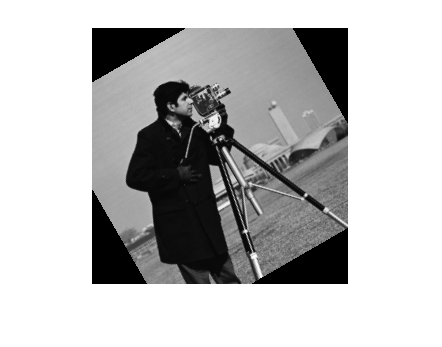

    rotatedImage = rotateImage(img, pi/6, 'linear');
    figure('name', 'Q3.1.2 / Q3.1.2 : pi/6 angle')
    imshow(rotatedImage)

## Question 3.1.3

We've added an addMargins flag to rotateImage() which results in a complete picture as output. See rotateImage() for further details.

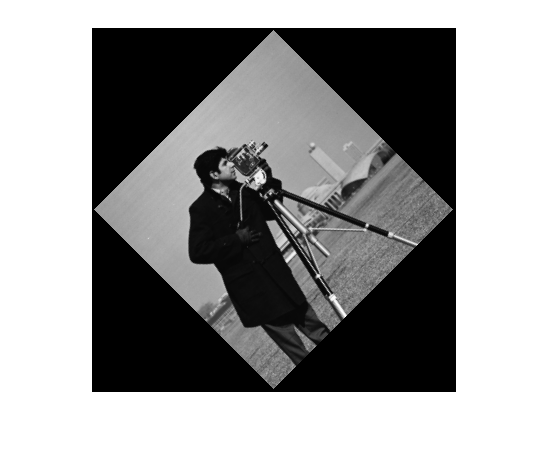

    figure('name', 'Image after 45deg rotation w/ constant border method')
    rotatedImage = rotateImage(img, pi/4, 'linear', 'constant', true);
    imshow(rotatedImage)

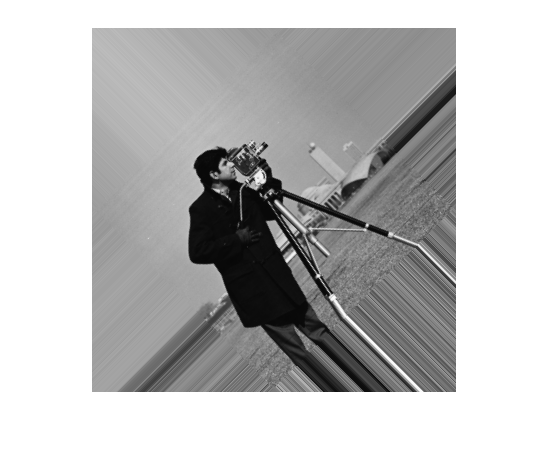

    figure('name', 'Image after 45deg rotation w/ nearest border method')
    rotatedImage = rotateImage(img, pi/4, 'linear', 'nearest', true);
    imshow(rotatedImage)

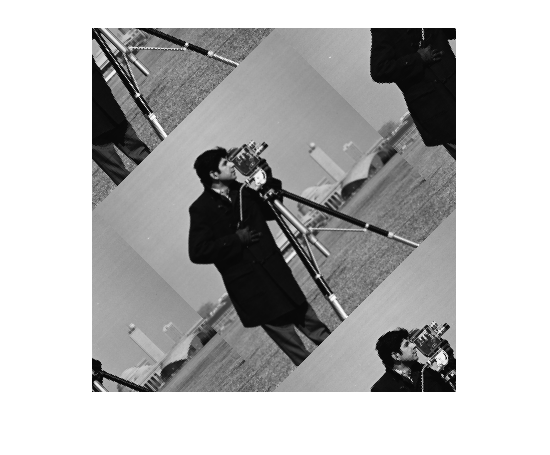

    figure('name', 'Image after 45deg rotation w/ periodic border method')
    rotatedImage = rotateImage(img, pi/4, 'linear', 'periodic', true);
    imshow(rotatedImage)

## Question 3.1.4

Processing time performance measure of both interpolation methods.

    disp('Processing time for nearest interpolation:')

Processing time for nearest interpolation:


    tic;
    rotateImage(img, pi/4, 'nearest');
    toc;

Elapsed time is 0.775070 seconds.


    disp('Processing time for (bi)linear interpolation:')

Processing time for (bi)linear interpolation:


    tic;
    rotateImage(img, pi/4, 'linear');
    toc;

Elapsed time is 0.806976 seconds.


## Question 3.1.5

The distance, between the original and interpolated version of the image is measured using Euclidean distance.

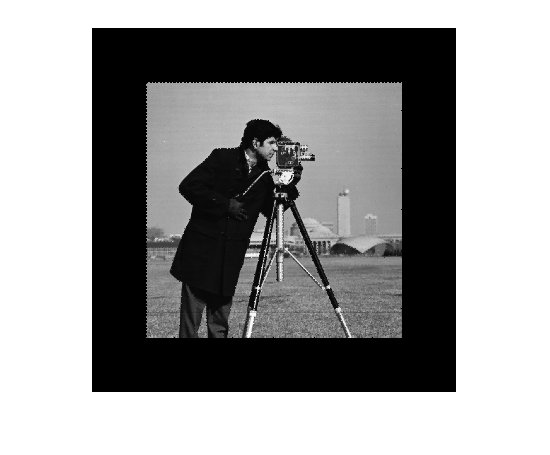

    imgNearest = rotateImage(img, pi/4, 'nearest', 'constant', true);
    imgNearest = rotateImage(imgNearest, -pi/4, 'nearest');
    figure('name', 'Image after double rotation w/ nearest interpolation')
    imshow(imgNearest)

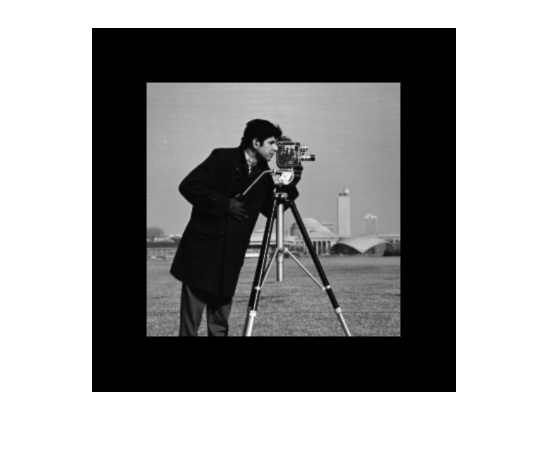

    
    imgLinear = rotateImage(img, pi/4, 'linear', 'constant', true);
    imgLinear = rotateImage(imgLinear, -pi/4, 'linear');
    figure('name', 'Image after double rotation w/ linear interpolation')
    imshow(imgLinear)

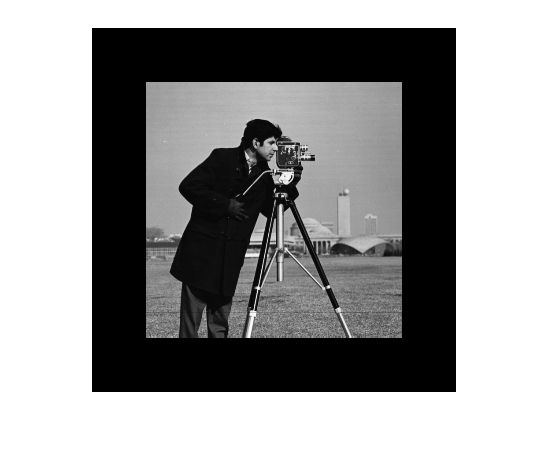

 
    borderedImage = borderImage(img, pi/4);
    figure('name', 'Image w/ border')
    imshow(borderedImage)

    
    distNearest = euclideanDistance(borderedImage, imgNearest);
    distLinear = euclideanDistance(borderedImage, imgLinear);
    distDiff = abs(distNearest - distLinear);

    fprintf('Distance (nearest): %f; distance (linear): %f, distance difference: %f\n', ...
        distNearest, distLinear, distDiff);

Distance (nearest): 871.617152; distance (linear): 867.616492, distance difference: 4.000659


## Question 4.1.1 / 4.1.3

Check out the implementation of myAffine(image, x1, y1, x2, y2, x3, y3, m, n, method)

## Question 4.1.2

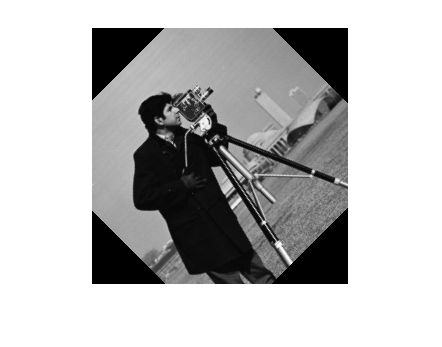

    [~, ~, topMargin, leftMargin] = imageRotationMargins(img, pi/4);
    [height, width] = size(img);
    figure('name', 'Image after affine transformation')
    rotatedImage = myAffine(img, -topMargin, width/2, height/2, ...
                   -leftMargin, height/2, width+leftMargin, height, width, 'linear');
    imshow(rotatedImage)

## Question 5.1.1

Check out the implementation of createProjectionMatrix(xy, uv)

## Question 5.1.2 / 5.1.4

Check out the implementation of myProjection(image, x1, y1, x2, y2, x3, y3, x4, y4, m, n, method)

## Question 5.1.3

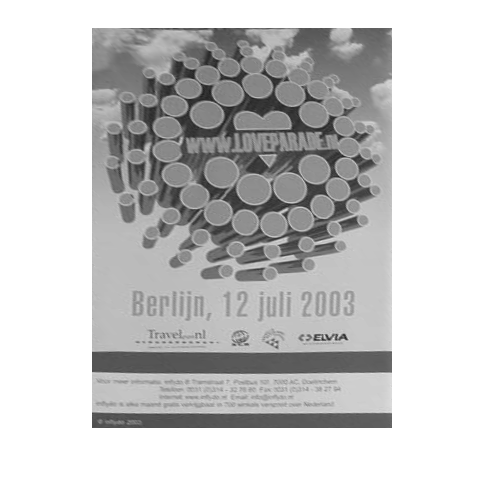

    flyers = im2double(imread('attachments/flyers.png'));
    %figure('name', 'Unstraightened flyers');
%     imshow(flyers)
%     [x, y] = ginput(4)
    x = [571.0000 356.5000 592.0000 817.0000];
    y = [190.2500 551.7500 583.2500 172.2500];

%     x = [152.5000, 391.5000, 303.5000, 101.5000];
%     y = [585, 393, 209, 373];
    
    figure('name', 'Frontal view of flyer');
    transformedFlyers = myProjection(flyers, x(1), y(1), ...
             x(2), y(2), x(3), y(3), x(4), y(4), 300, ...
             400, 'linear');
    imshow(transformedFlyers)